myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/electrical/"

myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/electrical/"

filepattern_docu_table = fullfile(myfolder,"*.xlsx")

filepattern_docu_table = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/electrical/*.xlsx"

filepattern_supra = fullfile(myfolder,"*supra.txt")

filepattern_supra = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/electrical/*supra.txt"

filepattern_connectivity = fullfile(myfolder,"*connectivity.txt")

filepattern_connectivity = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/electrical/*connectivity.txt"


filelist_docu_table = dir(filepattern_docu_table);
filelist_connectivity = dir(filepattern_connectivity);

all_data_connect = struct

all_data_connect = struct with no fields.


for k = 1:length(filelist_docu_table)
    basefilename = filelist_docu_table(k).name;
    fullfilename = fullfile(filelist_docu_table(k).folder, basefilename);
    thisDocuTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data_connect(k).namen= basefilename;
    all_data_connect(k).docutables = thisDocuTable;
end

for k = 1:length(filelist_connectivity)
    basefilename = filelist_connectivity(k).name;
    fullfilename = fullfile(filelist_connectivity(k).folder, basefilename);
    thisConnectTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data_connect(k).namen_connect= basefilename;
    all_data_connect(k).connect = thisConnectTable;
end


# tSynapse


variable_names_types = [["synapse_ID", "string"]; ...
                        ["pre_syn", "string"]; ...
                        ["post_syn", "string"]; ...
                        ["is_connected", "double"]; ...
                        ["IPSP_stim_1", "double"]; ...
                        ["IPSP_stim_2", "double"]; ...
                        ["IPSP_stim_3", "double"]; ...
                        ["IPSP_stim_4", "double"]; ...
			            ["mean_IPSP", "double"];...
			            ["Synapse_Amplitude", "double"]];%add: prechannelID
			            %["Synapse_IPSP", "double"]]; %besser Ipsp o Epsp
% Make table using fieldnames & value types from above
tsnyapse = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

id = 1

id = 1

for i=1:size(all_data_connect,2) %durch alle tables durch iterieren
    all_data_connect(i).tsynapse=tsnyapse;
    n=1;
    for channel_n = 1:10 %durch alle 10 channel iterieren
        
        if all_data_connect(i).docutables{channel_n,2} == 1
            S=strsplit(all_data_connect(i).namen_connect,"_");
            S=strjoin([S(2), S(3)],"_");
            cellIDpre = append(S,"_C", string(channel_n)); %je nachdem welcher Manipulator ==1, also included war;
            
            disp(cellIDpre);
            disp(channel_n);
            
        for channel_m = 1:10 %durch alle 10 channel iterieren
            if all_data_connect(i).docutables{channel_m,2} ==1
                S=strsplit(all_data_connect(i).namen_connect,"_");
                S=strjoin([S(2), S(3)],"_");
                cellIDpost = append(S,"_C", string(channel_m));%je nachdem welcher Manipulator ==1, also included war;
                disp(cellIDpost);
                disp(channel_m);
                if cellIDpre ~= cellIDpost %keine Connectivität bei C1=C1 
                all_data_connect(i).tsynapse(n,1)=array2table(id);
                all_data_connect(i).tsynapse(n,2)=array2table(cellIDpre);
                all_data_connect(i).tsynapse(n,3)=array2table(cellIDpost);
                jo = string(table2array(all_data_connect(i).docutables(channel_n,channel_m+2)));
                if jo=="1"
  
                colnames = all_data_connect(i).connect.Properties.VariableNames();

                for find_trace = 2:length(colnames)
                chan_name = strsplit(string(colnames(find_trace)), " ");
                chan_name=chan_name(2);
                if chan_name == string(channel_n)
                  presyn_trace=all_data_connect(i).connect(:,find_trace); %präsynapse 
                elseif chan_name == string(channel_m)
                  postsyn_trace=all_data_connect(i).connect(:,find_trace); %postsynapse
                end
                

                end
                all_data_connect(i).tsynapse(n,4)=array2table(1);

                end
                n=n+1 %Zähler für Spalten
                id = id + 1 %ID Zähler
                end 
            end
        end
        end
    
    end
end

20240823_006_C1


     1



20240823_006_C1


     1



20240823_006_C4


     4



n = 2

id = 2

20240823_006_C8


     8



n = 3

id = 3

20240823_006_C4


     4



20240823_006_C1


     1



n = 4

id = 4

20240823_006_C4


     4



20240823_006_C8


     8



n = 5

id = 5

20240823_006_C8


     8



20240823_006_C1


     1



n = 6

id = 6

20240823_006_C4


     4



n = 7

id = 7

20240823_006_C8


     8



20240826_002_C4


     4



20240826_002_C4


     4



20240826_002_C8


     8



n = 2

id = 8

20240826_002_C8


     8



20240826_002_C4


     4



n = 3

id = 9

20240826_002_C8


     8



20240828_000_C3


     3



20240828_000_C3


     3



20240828_000_C4


     4



n = 2

id = 10

20240828_000_C8


     8



n = 3

id = 11

20240828_000_C4


     4



20240828_000_C3


     3



n = 4

id = 12

20240828_000_C4


     4



20240828_000_C8


     8



n = 5

id = 13

20240828_000_C8


     8



20240828_000_C3


     3



n = 6

id = 14

20240828_000_C4


     4



n = 7

id = 15

20240828_000_C8


     8



    % colnames = all_data_connect(1).connect.Properties.VariableNames()
    % 
    % for find_trace = 2:length(colnames)
    % 
    %             chan_name = strsplit(string(colnames(find_trace)), " ")
    %             chan_name=chan_name(2)
    %             if chan_name == string(channel_n)
    %               presyn_trace=all_data_connect(1).connect(:,find_trace)  
    %             elseif chan_name == string(channel_m)
    %               postsyn_trace=all_data_connect(1).connect(:,find_trace)
    %             end
    %             %all_data_connect(i).tsynapse(n,4)=array2table(1)
    % 
    %             %postsyn_trace=all_data_connect(i).connect()
    % end 
    % 


                % diff_trace_segment = diff(table2array(presyn_trace));
                % diff_threshold = 2;
                % Stimulus_time = find(diff_trace_segment>diff_threshold, 1, "first")
                % plot(table2array(presyn_trace))
                % post_segment = (table2array(postsyn_trace))
                


% die Variable synapse zählt wie viele Synapsen in allen Experimenten verbunden sind
synapsen = 0 

synapsen = 0

% n_Synapse zählt die Synapsen die NICHT verbunden sind
n_synapse = 0

n_synapse = 0

% wie hoch ist die Wahrscheinl,ichkeit, dass eine Synapse gefunden wird, in
% dem jeweiligen Experiment
connectivity_per_exp = []


connectivity_per_exp =

     []



% loop geht durch alle Spalten von 1 bis zumletzten Eintrag 
for i = 1:length(all_data_connect)
    % zählen der Synapsen pro Experiment
    synapsen_y=0;
    % zählen der NICHT Synapsen pro Experiment
    synapsen_n=0;
    all_connect= all_data_connect(i).tsynapse.is_connected;
    for s = 1: length(all_connect)
    if all_connect(s) == 1
        synapsen = synapsen+1;
        synapsen_y= synapsen_y+1;
    else 
        n_synapse = n_synapse+1;
        synapsen_n= synapsen_n+1;
    end
    end
    prozent_pro_exp= synapsen_y/(synapsen_n+synapsen_y);
    connectivity_per_exp = [connectivity_per_exp,prozent_pro_exp];
    
end

synapsen

synapsen = 3

n_synapse

n_synapse = 11

prozent = synapsen/(n_synapse+synapsen)

prozent = 0.2143

connectivity_per_exp

connectivity_per_exp =     0.1667    1.0000         0


mean(connectivity_per_exp)

ans = 0.3889

times = (0.1:1.5:13.6)*20000

times =         2000       32000       62000       92000      122000      152000      182000      212000      242000      272000


pre_syn_cell = 4

post_syn_cell = 8

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -44.4412

min_second_stim = -44.4660

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -44.4727

avg_max = -44.0421

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.9496

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/electrical/20240823_006_C4__20240823_006_C8widerview_el_synapse_plot_rat.pdf"

pre_syn_cell = 4

post_syn_cell = 8

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -49.5667

min_second_stim = -49.5590

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -49.5213

avg_max = -48.2975

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 1.1726

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/electrical/20240826_002_C4__20240826_002_C8widerview_el_synapse_plot_rat.pdf"

pre_syn_cell = 8

post_syn_cell = 4

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -58.4198

min_second_stim = -58.2993

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -58.4309

avg_max = -56.3000

all_data_connect = 1×3 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.3617

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/electrical/20240826_002_C8__20240826_002_C4widerview_el_synapse_plot_rat.pdf"

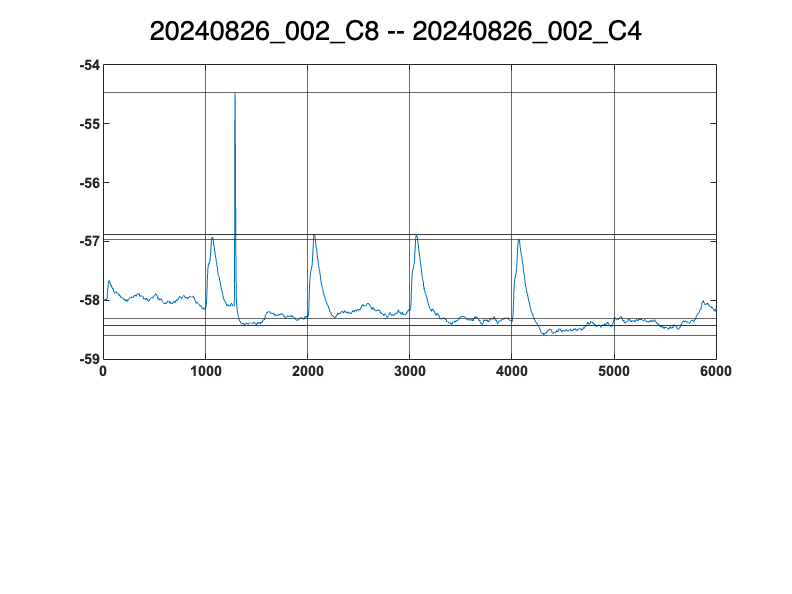

for j = 1:length(all_data_connect)
    for l = 1:height(all_data_connect(j).tsynapse)
        if all_data_connect(j).tsynapse.is_connected(l) == 1
            pre_syn_cell = strsplit(all_data_connect(j).tsynapse.pre_syn(l), "C");
            post_syn_cell = strsplit(all_data_connect(j).tsynapse.post_syn(l), "C");
            pre_syn_cell = double(pre_syn_cell(2))
            post_syn_cell = double(post_syn_cell(2))
            timestart= times(pre_syn_cell);
            properties = all_data_connect(j).connect.Properties.VariableNames;
            post_column=0;
            for entries = 1:length(properties)
                colname=(strsplit(string(properties(entries))," "))
                colname = colname(length(colname))
                if colname == string(post_syn_cell)
                      post_column = entries;
                end 
            end
            whole_stim = table2array(all_data_connect(j).connect(timestart-1000:(timestart+5000), post_column));
            first_stim = table2array(all_data_connect(j).connect(timestart:(timestart+1000), post_column));
            second_stim = table2array(all_data_connect(j).connect((timestart+1000):(timestart+2000), post_column));
            third_stim = table2array(all_data_connect(j).connect((timestart+2000):(timestart+3000), post_column));
            fourth_stim = table2array(all_data_connect(j).connect((timestart+3000):(timestart+4000), post_column));
            max_first_stim=max(first_stim);
            min_first_stim=min(first_stim)
            max_second_stim=max(second_stim);
            min_second_stim=min(second_stim)
            max_third_stim=max(third_stim);
            min_third_stim=min(third_stim);
            max_fourth_stim=max(fourth_stim);
            min_fourth_stim=min(fourth_stim);
            all_data_connect(j).tsynapse.IPSP_stim_1(l) = max_first_stim-min_first_stim
            all_data_connect(j).tsynapse.IPSP_stim_2(l) = max_second_stim-min_second_stim
            all_data_connect(j).tsynapse.IPSP_stim_3(l) = max_third_stim-min_third_stim
            all_data_connect(j).tsynapse.IPSP_stim_4(l) = max_fourth_stim-min_fourth_stim
            avg_min=mean([min_fourth_stim,min_third_stim,min_second_stim, min_first_stim])
            avg_max=mean([max_first_stim, max_fourth_stim, max_third_stim, max_second_stim])
            all_data_connect(j).tsynapse.mean_IPSP(l)= avg_max-avg_min
            
            PPR = all_data_connect(j).tsynapse.IPSP_stim_2(l)/all_data_connect(j).tsynapse.IPSP_stim_1(l)
            
                         clf

            
            subplot(3,1,[1:2])
             plot(whole_stim)
             yline(min_first_stim)
             yline(max_first_stim)
            % plot(second_stim)
             yline(min_second_stim)
             yline(max_second_stim)
            %             figure
            % plot(third_stim)
             yline(min_third_stim)
             yline(max_third_stim)
            %             figure
            % plot(fourth_stim)
             yline(min_fourth_stim)
             yline(max_fourth_stim)
             xline(1000)
             xline(2000)
             xline(3000)
             xline(4000)
             xline(5000)
             xlim([0 6000])
             
             sgtitle(strcat(char(all_data_connect(j).tsynapse.pre_syn(l))," -- ",string(all_data_connect(j).tsynapse.post_syn(l))), "Interpreter", "none")
            


            filename_PLOT =  strcat("/Users/emiliathoma/Desktop/synapse_plots_rat/electrical/",strcat(char(all_data_connect(j).tsynapse.pre_syn(l)),"__",string(all_data_connect(j).tsynapse.post_syn(l))),"widerview_el_synapse_plot_rat.pdf")
            set(findobj(gcf,'type','axes'),'FontName','Arial','FontSize',8,'FontWeight','Bold', 'LineWidth', 1);
            set(gcf, "Units", "centimeters");
            screenposition = get(gcf, "Position");
            set(gcf, ...
                "PaperPosition",[0 0 22 34], ...
                "PaperSize", [22 33]) 

            print(gcf, filename_PLOT, "-dpdf", "-vector")
            


        end 
    end 
end 

for s = 1:length(all_data_connect)
name = strsplit(all_data_connect(s).namen, "_docu_table.xlsx")
name = string(name(1))
writetable(all_data_connect(s).tsynapse,append("/Users/emiliathoma/Desktop/rat/electrical/", name,   "_elec_synapse_rat.csv") )










end

name = 1×2 cell array
    {'ET_20240823_006'}    {0×0 char}


name = "ET_20240823_006"

name = 1×2 cell array
    {'ET_20240826_002'}    {0×0 char}


name = "ET_20240826_002"

name = 1×2 cell array
    {'ET_20240828_000'}    {0×0 char}


name = "ET_20240828_000"